# **MATLAB Live Script that will export the Photoionisation Energy and Fluorescence Database (PIEFD) into a MATLAB data format, for easy loading and reading of the PIEFD**

The **Photoionisation Energy and Fluorescence Database (PIEFD) **local MATLAB reference file 'PIEFD_PCC.mat' is created and saved here.

- You do not need to run this program, as the database will always be up-to-date with all released versions.

- This MATLAB Live Script is saved and stored here for future reference and in case of any future updates to the PIEFDdatabase.

The data that forms the PIEFD database is taken primarily from the following source;

- [1] [https://xdb.lbl.gov/](https://xdb.lbl.gov/) (X-Ray Data Booklet)

In order to connect a Microsoft Access database (*.mdb, *.accdb) to MATLAB, you must ensure that you have the correct ODBC connected for Windows and a step-by-step guide can be found here: [https://ch.mathworks.com/help/releases/R2017a/database/ug/microsoft-access-odbc-windows.html](https://ch.mathworks.com/help/releases/R2017a/database/ug/microsoft-access-odbc-windows.html)

Just in case you don't have the correct ODBC drivers, I found that installing these three drivers from Microsoft made the MATLAB Database Explorer work fine;

- [https://docs.microsoft.com/en-us/sql/ssms/download-sql-server-management-studio-ssms?redirectedfrom=MSDN&view=sql-server-ver15](https://docs.microsoft.com/en-us/sql/ssms/download-sql-server-management-studio-ssms?redirectedfrom=MSDN&view=sql-server-ver15)

- [https://docs.microsoft.com/en-us/sql/connect/odbc/download-odbc-driver-for-sql-server?view=sql-server-ver15](https://docs.microsoft.com/en-us/sql/connect/odbc/download-odbc-driver-for-sql-server?view=sql-server-ver15)

- (select the x64 bit installation here) [https://www.microsoft.com/en-us/download/details.aspx?id=13255](https://www.microsoft.com/en-us/download/details.aspx?id=13255)

**(1)     :    Connecting the the PIEFD (After you have done this: **[**Set up the data source using Database Explorer.**](https://ch.mathworks.com/help/releases/R2017a/database/ug/microsoft-access-odbc-windows.html#bt4pjhl)**)**

close all; clear all;
conn            = database('PIEFD_PCC','admin','admin');
PIEFD_version   = "PIEFD_v1";
PIEFD_PCC       = sqlread(conn,PIEFD_version); close(conn);
PIEFD_PCC

PIEFD_PCC = 118×52 table
    ID      ATOM_NAME       ATOM_SYMB    ATOM_ZNUM      ELECT_CONFIG       BE_K     BE_L1    BE_L2    BE_L3    BE_M1    BE_M2    BE_M3    BE_M4    BE_M5    BE_N1    BE_N2    BE_N3    BE_N4    BE_N5    BE_N6    BE_N7    BE_O1    BE_O2    BE_O3    BE_O4    BE_O5    BE_P1    BE_P2    BE_P3    FLUO_PE_K_L3    FLUO_PE_K_L2    FLUO_PE_K_M3    FLUO_PE_L3_M5    FLUO_PE_L3_M4    FLUO_PE_L2_M4

**(2)     :    Saving the database as a MATLAB table for quick future reference**

path_name = "G:\My Drive\GitHub\ADRESSTools\ADRESSTools_Dionysus\MaterialsDatabase_PCC\Photoionisation Energy and Fluorescence Database (PIEFD)\data\";
file_name = "PIEFD_PCC";
save_fullfile = path_name + file_name;
save(char(save_fullfile + ".mat"), 'PIEFD_PCC');

Thus, when you can make any new material additions / changes within the 'PIEFD_PCC.accdb' file using Microsoft Access, you can run this afterwards to propagate the changes you make. This will update the MATLAB version of the database, which is then referenced in the many scripts of ARPESGUI.

# **Using 'get_piefd_props()' to extract material properties for any element / compound that is defined in the database**

For reference, the binding / fluorescence energies are defined in terms of the IUPAC notation, where;

- K       =     1s1/2     (n = 1, l = 0, j=1/2)

- L1     =     2s1/2     (n = 2, l = 0, j=1/2)

- L2     =     2p1/2     (n = 2, l = 1, j=1/2)

- L3     =     2p3/2     (n = 2, l = 1, j=3/2)

- M1    =     3s1/2     (n = 3, l = 0, j=1/2)

- M2    =     3p1/2     (n = 3, l = 1, j=1/2)

- M3    =     3p3/2     (n = 3, l = 1, j=3/2)

- M4    =     3d3/2     (n = 3, l = 2, j=3/2)

- M5    =     3d5/2     (n = 3, l = 2, j=5/2)

- N1    =     4s1/2     (n =4, l = 0, j=1/2)

- N2    =     4p1/2     (n = 4, l = 1, j=1/2)

- N3    =     4p3/2     (n = 4, l = 1, j=3/2)

- N4    =     4d3/2     (n = 4, l = 2, j=3/2)

- N5    =     4d5/2     (n = 4, l = 2, j=5/2)

- N6    =     4f5/2     (n = 4, l = 3, j=5/2)

- N7    =     4f7/2     (n = 4, l = 3, j=7/2)

- O1    =     5s1/2     (n = 5, l = 0, j=1/2)

- O2    =     5p1/2     (n = 5, l = 1, j=1/2)

- O3    =     5p3/2     (n = 5, l = 1, j=3/2)

- O4    =     5d3/2     (n = 5, l = 2, j=3/2)

- O5    =     5d5/2     (n = 5, l = 2, j=5/2)

- P1    =     6s1/2     (n = 6, l = 0, j=1/2)

- P2    =     6p1/2     (n = 6, l = 1, j=1/2)

- P3    =     6p3/2     (n = 6, l = 1, j=3/2)

% Using the 'get_piefd_props()' function to extract PIEFD data
piefd_props = get_piefd_props('Si'); piefd_props

piefd_props = 1×52 table
    ID     ATOM_NAME     ATOM_SYMB    ATOM_ZNUM      ELECT_CONFIG      BE_K    BE_L1    BE_L2    BE_L3    BE_M1    BE_M2    BE_M3    BE_M4    BE_M5    BE_N1    BE_N2    BE_N3    BE_N4    BE_N5    BE_N6    BE_N7    BE_O1    BE_O2    BE_O3    BE_O4    BE_O5    BE_P1    BE_P2    BE_P3    FLUO_PE_K_L3    FLUO_PE_K_L2    FLUO_PE_K_M3    FLUO_PE_L3_M5    FLUO_PE_L3_M4    FLUO_PE_L2_M4

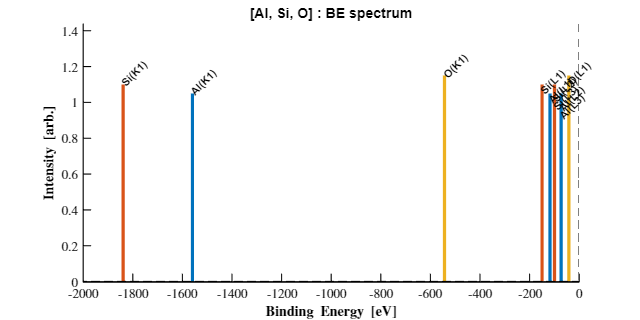

% Using the 'view_be_spectrum()' function to view binding energy spectrum of elements
view_be_spectrum(["Al", "Si", "O"]);

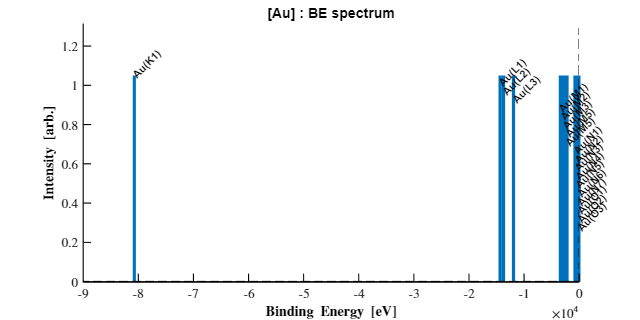

view_be_spectrum("Au");